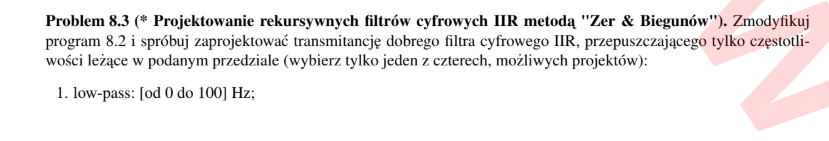

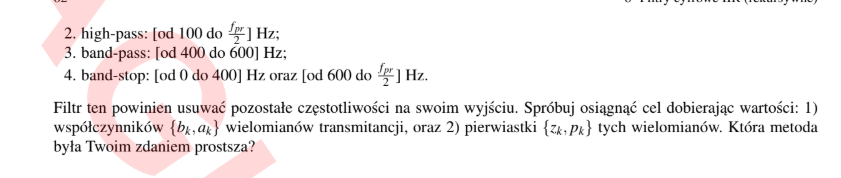

% 3. band-pass [od 400 do 600] Hz
% 2) dobieram wartości wartości współczynników

% chce miec zero na 100 i 900
% zespolone pierwiastki
% okolo 0.4 + 0.9j i jego sprzezenie

% chce miec bieguny na 400, 500 i 600
% dla 500 bedzie
% root = -j

% Wybor/projekt wspolczynnikow filtra cyfrowego IIR
fpr = 2000;                           % czestotliwosc probkowania
if(1)  % ### dobor wartosci wspolczynnikow wielomianow transmitancji
   b = poly([0.95 + j*0.3, 0.95 - j*0.3, -0.95 + j*0.3, -0.95 - j*0.3,])
   % b = [0.5,1];                         % [ b0, b1 ]
   a = poly([0.99*j, -0.99*j, 0.15 + 0.98*j, -0.15 + 0.98*j, 0.15 - 0.98*j, -0.15 - 0.98*j]);           % [ a0=1, a2, a3, a4]
   z = roots(b), p = roots(a),        % [b,a] --> [z,p]
else   % ### dobor miejsc zerowych wielomianow transmitancji
   gain = 0.001;
   z = [ 0.99, 0.99   ] .* exp(j*2*pi*[ 100, 900]/fpr);   z = [z conj(z)];  
   p = [ 0.99, 0.99, 0.99, 0.99, 0.99 ] .* exp(j*2*pi*[ 400, 450, 500, 550, 600 ]/fpr);   p = [p conj(p)];
   b = real( gain*poly(z) ), a = real( poly(p) ),  % [z,p] --> [b,a]
end

b =     1.0000         0   -1.6250         0    0.9851


z =   -0.9500 + 0.3000i
  -0.9500 - 0.3000i
   0.9500 + 0.3000i
   0.9500 - 0.3000i


p =   -0.1500 + 0.9800i
  -0.1500 - 0.9800i
   0.1500 + 0.9800i
   0.1500 - 0.9800i
  -0.0000 + 0.9900i
  -0.0000 - 0.9900i


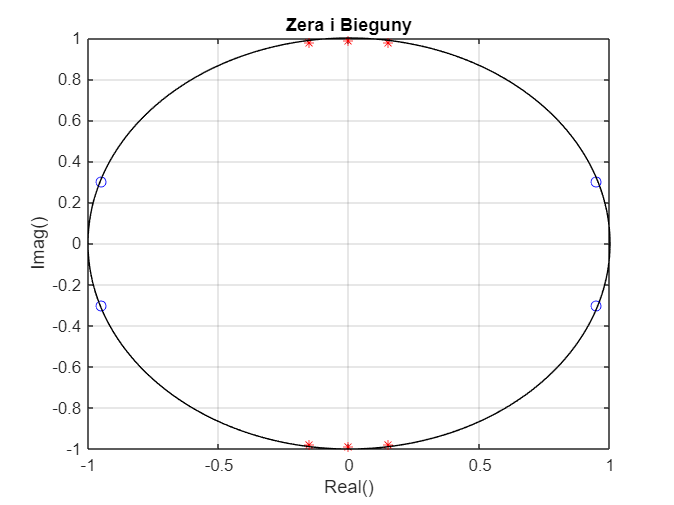

figure;
alfa = 0 : pi/1000 : 2*pi; c=cos(alfa); s=sin(alfa);
plot(real(z),imag(z),'bo', real(p),imag(p),'r*',c,s,'k-'); grid;
title('Zera i Bieguny'); xlabel('Real()'); ylabel('Imag()');

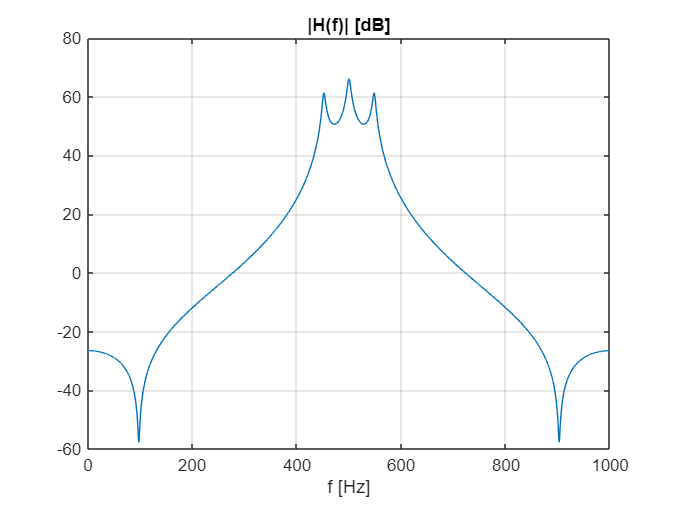

% Weryfikacja odpowiedzi filtra: amplitudowej, fazowej, impulsowej, skokowej
f = 0 : 0.1 : 1000;                 % czestotliwosc w hercach
wn = 2*pi*f/fpr;                    % czestotliwosc katowa
zz = exp(-j*wn);                    % zmienna "z" transformacji Z (u nas z^(-1))
H = polyval(b(end:-1:1),zz) ./ polyval( a(end:-1:1),zz); % stosunek dwoch wielomianow
% H = freqz(b,a,f,fpr)                                    % alternatywna funkcja Matlab
figure; plot(f,20*log10(abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;

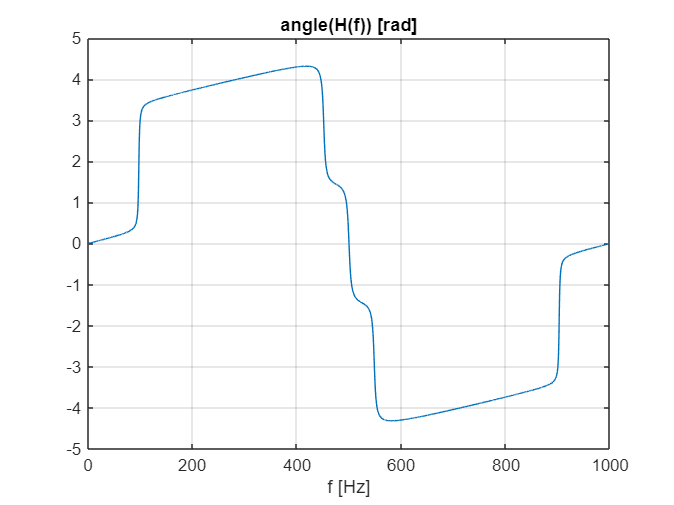

figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;


zz = exp(j*wn);                     % zmienna transformacji Z
H = polyval(b,zz) ./ polyval(a,zz); % stosunek dwoch wielomianow dla zz=exp(j*om)
% H = freqz(b,a,f,fpr)              % alternatywna funkcja Matlaba
figure; plot(f,20*log10(abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;

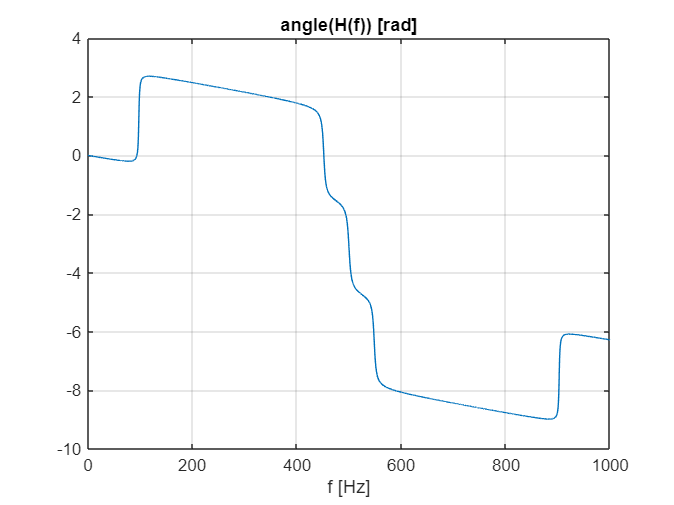

figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid;

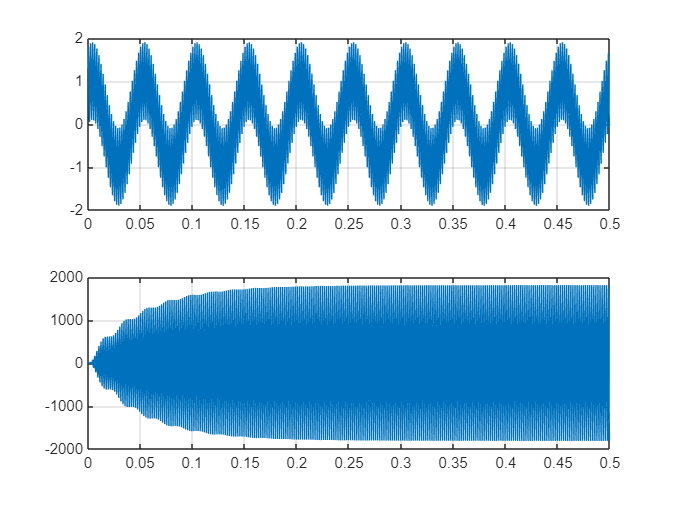


% Sygnal wejsciowy x(n) - dwie sinusoidy: 20 and 500 Hz
Nx = 1000;                                       % liczba probek sygnalu
dt = 1/fpr; t = dt*(0:Nx-1);                     % chwile probkowania
%x = zeros(1,Nx); x(1) = 1;                      % sygnal delta Kroneckera (impuls jednostkowy)
x = sin(2*pi*20*t+pi/3) + sin(2*pi*500*t+pi/7);  % suma dwoch sinusow

% Rekursywna filtracja cyfrowa IIR: x(n) --> [ b, a ] --> y(n)
% y=filter(b,a,x);                           % funkcja Matlaba
M = length(b);                               % liczba wspolczynnikow {b}
N = length(a); a = a(2:N); N=N-1;            % liczba wspolczynnikow {a}, usun a0=1
bx = zeros(1,M);                             % bufor bx na probki wejsciowe x(n)
by = zeros(1,N);                             % bufor by na probki wyjsciowe y(n)
for n = 1 : Nx                               % PETLA GLOWNA
    bx = [ x(n) bx(1:M-1) ];                 % nowa probka x(n) na poczatek bufora bx
    y(n) = sum( bx .* b ) - sum( by .* a );  % filtracja = dwie srednie wazone, y(n)=?
    by = [ y(n) by(1:N-1) ];                 % zapamietanie y(n) w buforze by
end                                          %

% RYSUNKI: porownanie wejscia i wyjscia filtra
figure;
subplot(211); plot(t,x); grid;               % sygnal wejsciowy x(n)
subplot(212); plot(t,y); grid;         % sygnal wyjsciowy y(n)

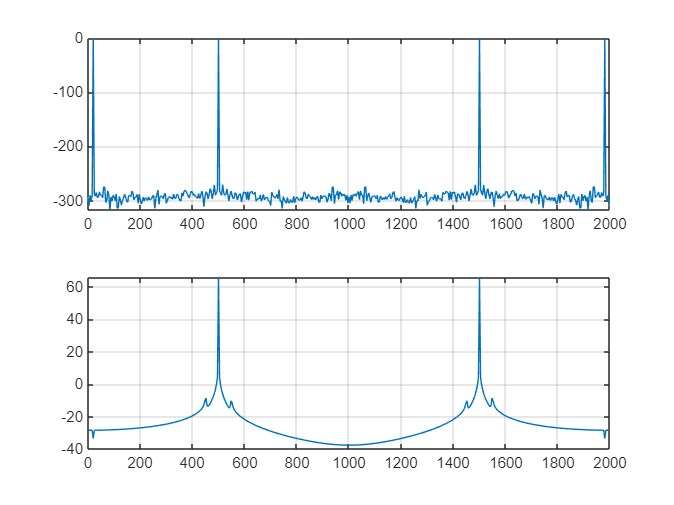

figure; % widma FFT drugicj polowek sygnalow x(n) i y(n) (bez stanow przejsciowych)
k=Nx/2+1:Nx;  f0 = fpr/(Nx/2);  f=f0*(0:Nx/2-1); 
subplot(211); plot(f,20*log10(abs(2*fft(x(k)))/(Nx/2))); grid; 
subplot(212); plot(f,20*log10(abs(2*fft(y(k)))/(Nx/2))); grid;